clear clc
syms vin v1 v2 v3 s c r n1 n2 n3 w H positive

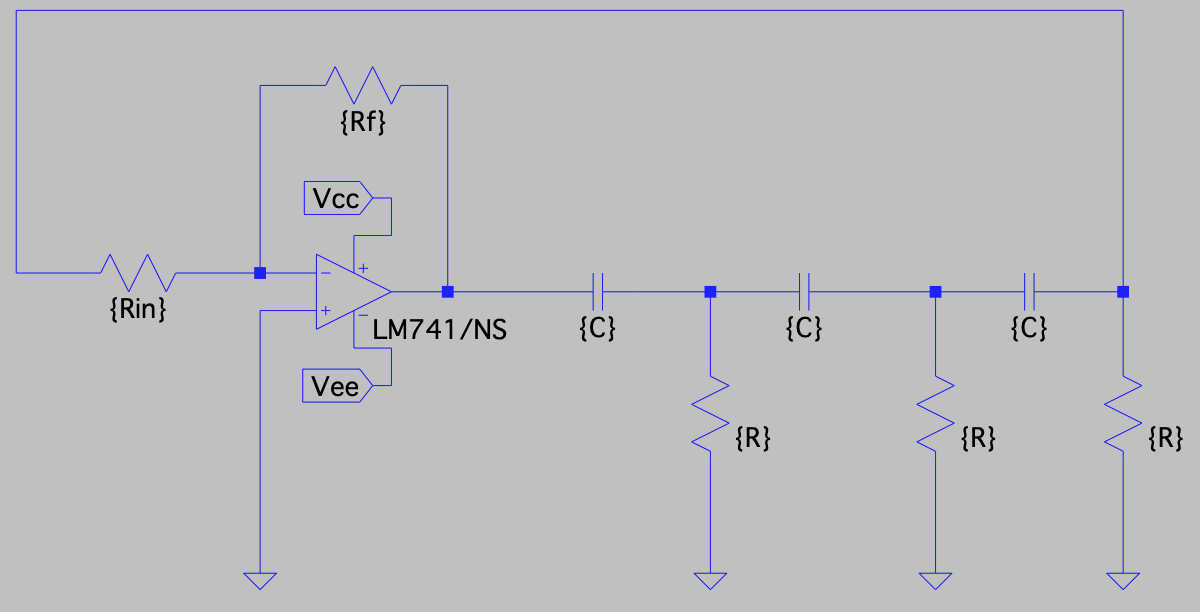

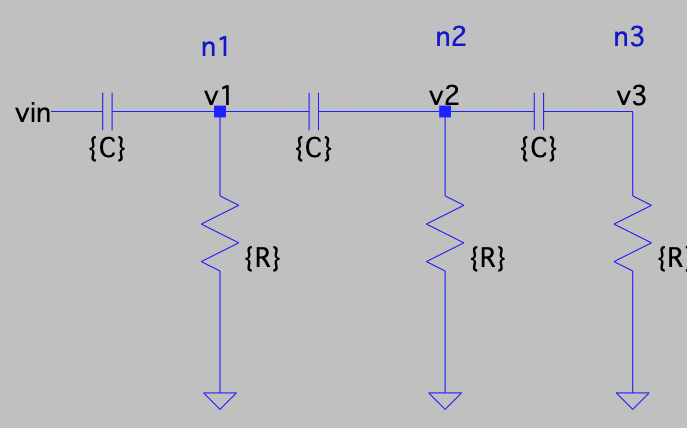

Definindo os nos

n1 = (v1 - vin)/(1/(s*c)) + v1/r + (v1-v2)/(1/(s*c)) == 0

$$n1 = \frac{v_{1}}{r}+c\,s\,\left(v_{1}-v_{2}\right)+c\,s\,\left(v_{1}-\mathrm{vin}\right)=0$$

n2 = (v2 - v1)/(1/(s*c)) + v2/r + (v2-v3)/(1/(s*c)) == 0

$$n2 = \frac{v_{2}}{r}-c\,s\,\left(v_{1}-v_{2}\right)+c\,s\,\left(v_{2}-v_{3}\right)=0$$

n3 = (v3-v2)/(1/(s*c)) + v3/r == 0

$$n3 = \frac{v_{3}}{r}-c\,s\,\left(v_{2}-v_{3}\right)=0$$

Isolando v2 a partir do no 3

v2 = solve(n3, v2)

$$v2 = \frac{\frac{v_{3}}{r}+c\,s\,v_{3}}{c\,s}$$

Substituindo v2 no no 2

n2 = subs(n2)

$$n2 = \frac{\frac{v_{3}}{r}+c\,s\,v_{3}}{c\,r\,s}-c\,s\,\left(v_{3}-\frac{\frac{v_{3}}{r}+c\,s\,v_{3}}{c\,s}\right)-c\,s\,\left(v_{1}-\frac{\frac{v_{3}}{r}+c\,s\,v_{3}}{c\,s}\right)=0$$

Substituindo v2 no no 1

n1 = subs(n1)

$$n1 = \frac{v_{1}}{r}+c\,s\,\left(v_{1}-\frac{\frac{v_{3}}{r}+c\,s\,v_{3}}{c\,s}\right)+c\,s\,\left(v_{1}-\mathrm{vin}\right)=0$$

Isolando v1 no no 2

v1 = solve(n2, v1)

$$v1 = \frac{v_{3}\,c^{2}\,r^{2}\,s^{2}+3\,v_{3}\,c\,r\,s+v_{3}}{c^{2}\,r^{2}\,s^{2}}$$

Aplicando v1 no no 1

n1 = subs(n1)

$$n1 = \begin{array}{l} \frac{v_{3}\,c^{2}\,r^{2}\,s^{2}+3\,v_{3}\,c\,r\,s+v_{3}}{c^{2}\,r^{3}\,s^{2}}-c\,s\,\left(\mathrm{vin}-\sigma_{1}\right)-c\,s\,\left(\frac{\frac{v_{3}}{r}+c\,s\,v_{3}}{c\,s}-\sigma_{1}\right)=0\\ \mathrm{where}\\ \sigma_{1}=\frac{v_{3}\,c^{2}\,r^{2}\,s^{2}+3\,v_{3}\,c\,r\,s+v_{3}}{c^{2}\,r^{2}\,s^{2}} \end{array}$$

Isolando vin

vin = solve(n1, vin)

$$vin = \frac{v_{3}\,c^{3}\,r^{3}\,s^{3}+6\,v_{3}\,c^{2}\,r^{2}\,s^{2}+5\,v_{3}\,c\,r\,s+v_{3}}{c^{3}\,r^{3}\,s^{3}}$$

  H = simplify(v3/vin)

$$H = \frac{c^{3}\,r^{3}\,s^{3}}{c^{3}\,r^{3}\,s^{3}+6\,c^{2}\,r^{2}\,s^{2}+5\,c\,r\,s+1}$$

Fazendo s=jw

s = 1i*w;
H = subs(H)

$$H = -\frac{c^{3}\,r^{3}\,w^{3}\,\mathrm{i}}{-c^{3}\,r^{3}\,w^{3}\,\mathrm{i}-6\,c^{2}\,r^{2}\,w^{2}+5\,c\,r\,w\,\mathrm{i}+1}$$

Feito isso precisamos isolar a parte real do denominado

[numH, denH] = numden(H);
    denHreal = subs(denH, 1i, 0);

Igualando a zero e extraindo W temos

denHreal = denHreal == 0

$$denHreal = 6\,c^{2}\,r^{2}\,w^{2}-1=0$$

  w = solve(denHreal, w);

  w = simplify(w)

$$w = \frac{\sqrt{6}}{6\,c\,r}$$

Agora, para demonstrar o ganho substituimos a frequencia encontrada na equacao. Dessa forma:

A = subs(H)

$$A = -\frac{1}{29}$$